# Exploring autocorrelation

### Functions

**Generating data:**

- **filter.m** : Generate data with a variety of smoothing & whitening filters, including autoregressive noise and moving averages

- **noise_arp.m** (CANlab): Generate autoregressive noise of order p

**Fitting autoregressive models:**

- **fit_gls.m : **Fit an AR(p) model using generalized least squares

- **aryule.m** : Estimate Yule-walker coeffiicents for autocorrelation

- **arp_V.m** (CANlab): generate autocorrelation matrix V, whitening matrix K, and ACF for a series of AR coefficients

- **spm_Q.m** (SPM): generate autocorrelation matrix V and whitening matrix K for a series of AR coefficients

**Calculating autocorrelation:**

- **xcorr.m** : General cross-correlation function that can estimate the ACF

- **parcorr.m** (Econometrics): Estimate sample partial autocorrelation function (PACF) and confidence bounds

- **autocorr.m **(Econometrics): Sample [autocorrelation function](https://www.mathworks.com/help/releases/R2022b/econ/autocorr.html#btzjcln-4) (ACF) `acf` and associated lags, and confidence bounds

- **crosscorr.m** (Econometrics): General cross-correlation function that can estimate the ACF

- **lbqtest.m** (Econometrics): rejection decision `h` from a [Ljung-Box Q-test](https://www.mathworks.com/help/releases/R2022b/econ/lbqtest.html#bt07mge-3) for autocorrelation in the residual series

#### **Notes**

- The aryule formulation implemented in a way that gives its coefficients the opposite sign from the way the autocorrelated noise is generated here (which is more intuitive). The aryule coefficients thus give you those related to the whitening matrix K rather than the autoregressive coefficients and autocorrelation matrix V.   If we want AR coefficients, we need to multiply arcoeffs from aryule by -1. 

- spm_Q may give the wrong values for ar order > 1.  Need to check this.

#### **References**

Box, G. E. P., G. M. Jenkins, and G. C. Reinsel. Time Series Analysis: Forecasting and Control. 3rd edition. Upper Saddle River, NJ: Prentice-Hall, 1994.

**Useful websites and lectures**

- https://mcs.utm.utoronto.ca/~nosedal/sta457/ar1-and-ar2.pdf

- https://www.stat.berkeley.edu/~bartlett/courses/153-fall2010/lectures/3.pdf

- https://online.stat.psu.edu/stat462/node/189/

#### Outstanding questions

- I can't get es2true and es_w_true from V to match. Is this a problem? Why not?

- What should the scale be of K (relative to V) so that the whitening is correct

- To create ACFs we may need to multiply by sigma^2 (variance)

### Demo: Show the functional form of several kinds of correlated error matrices (V)

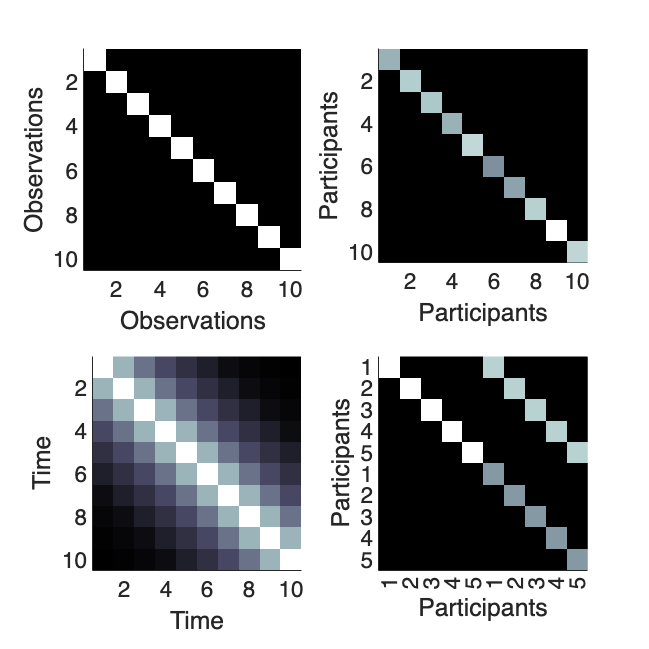

create_figure('cov e', 2, 2);
colormap bone;

X = eye(10); imagesc(X); set(gca, 'YDir', 'reverse', 'FontSize', 18); axis tight
xlabel('Observations'); ylabel('Observations')

% robust regression

subplot(2, 2, 2); set(gca, 'YDir', 'reverse', 'FontSize', 18); axis tight
rho = .7; 
X = diag(0.5 * ones(10, 1) + 0.5 * unifrnd(0, 1, 10, 1)); 
imagesc(X);
xlabel('Participants'); ylabel('Participants')

% time series

subplot(2, 2, 3); set(gca, 'YDir', 'reverse', 'FontSize', 18); axis tight
rho = .7; 
X = toeplitz([1 rho rho^2 rho^3 rho^4 rho^5 rho^7 rho^8 rho^9 rho^10]);
imagesc(X);
xlabel('Time'); ylabel('Time')

% subject series
subplot(2, 2, 4); set(gca, 'YDir', 'reverse', 'FontSize', 18); axis tight
rho = .7; k = .4;
X = diag([1 1 1 1 1 .6 .6 .6 .6 .6]);
X = X + diag([.8 .8 .8 .8 .8], 5);
imagesc(X);
xlabel('Participants'); ylabel('Participants')
set(gca, 'XTick', 1:10, 'XTickLabel', 1:5, 'YTick', 1:10, 'YTickLabel', 1:5)

n = 100;    % number of time points

rho = 0.7;  % rho autocorrelation param for AR(1) model 

[V, K, acf_true] = arp_V(rho, n);

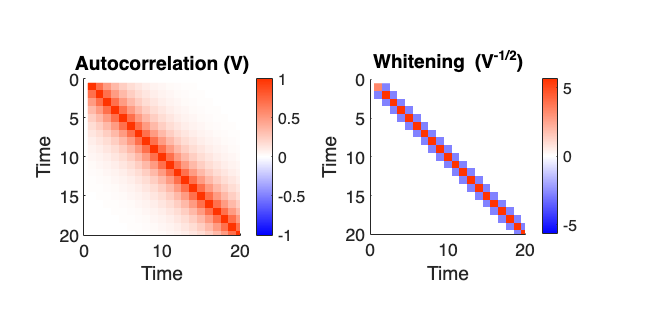

%% NOTE: V here is autocorrelation, but the V used in GLS is related to autocovariance I believe

create_figure('V', 1, 2);
imagesc(V); colorbar
title('Autocorrelation (V)')
set(gca, 'YDir', 'Reverse'); axis tight
axis image
% zoom in
set(gca, 'XLim', [0 20], 'YLim', [0 20], 'CLim', [0 1])
canlab_redblue_symmetric_colormap
xlabel('Time'), ylabel('Time')

subplot(1, 2, 2)
imagesc(K)
title('Whitening (V^{-1/2})')
colorbar
set(gca, 'YDir', 'Reverse'); axis tight
axis image
% zoom in
set(gca, 'XLim', [0 20], 'YLim', [0 20])
%colormap bone
canlab_redblue_symmetric_colormap
xlabel('Time'), ylabel('Time')

In SPM, you can do it this way:

#### Generate noise with known AR(1) filter

There are several ways of doing this:

- Manual calculation

- Digital filter with a rational transfer function

- Filtering matrix

n = 100;
eta = randn(n, 1); % some data, the ideal whitened error timeseries.  where \epsilon(t) ~ N(0,\sigma^2) 

% manual generation: e(t) = \rho e(t-1) + \eta(t)
es = eta(1);
for i = 2:length(eta)
    es(i, 1) = rho * es(i - 1) + eta(i);
end

% filter.m
% - To use the filter function with the b coefficients from an FIR filter, use y = filter(b,1,x)
% - For moving average of past 5 elements, b = [1 1 1 1 1]/n
% es2 = filter([1 rho], 1, eta);  % This is not right

% Create AR noise using the filter command.
% The AR model is: y(t) = phi1*y(t-1) + phi2*y(t-2) + phi3*y(t-3) + e(t)
% The filter command uses the denominator polynomial [1 -phi1 -phi2 -phi3]
es2 = filter(1, [1, -rho], eta);

corr(es, es2)

ans = 1


% create_figure('ts')
% plot(eta)
% plot(es2)
% plot(es3)


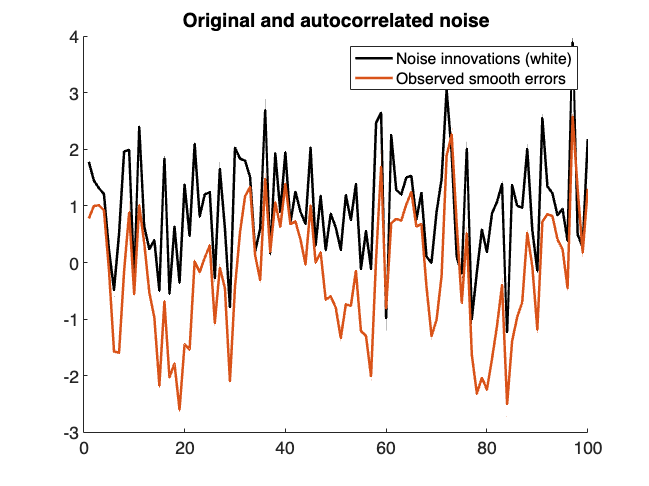

create_figure('e'); 
plot(1 + eta, 'k', 'LineWidth', 2)

hold on; 
plot(es, 'LineWidth', 2)
legend({'Noise innovations (white)' 'Observed smooth errors'})
title('Original and autocorrelated noise')

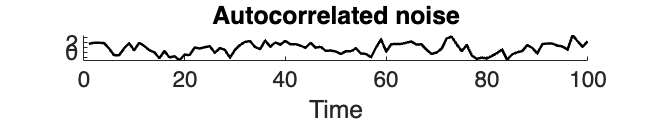


create_figure('e_for_fig');  % for book figure
plot(1 + es, 'k', 'LineWidth', 2)
title('Autocorrelated noise')
xlabel('Time')
set(gca, 'FontSize', 18)

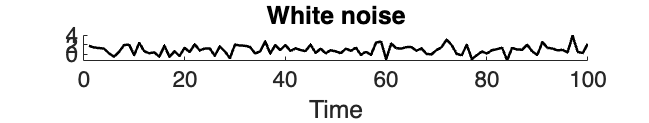

set(gcf, 'Position', [569         705        1121         212]) % tor laptop 2024

create_figure('eta_for_fig');  % for book figure
plot(1 + eta, 'k', 'LineWidth', 2)
title('White noise')
xlabel('Time')
set(gca, 'FontSize', 18)

set(gcf, 'Position', [569         705        1121         212]) % tor laptop 2024


### Plot true autocorrelation function

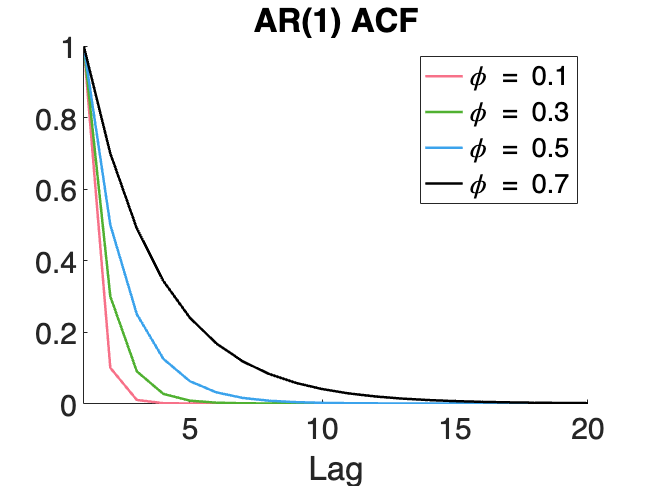


create_figure('acf'); %, 1, 3);

title('AR(1) ACF')
xlabel('Lag')
set(gca, 'FontSize', 24)

colors = seaborn_colors(3);

% [~, ~, acf_to_plot] = arp_V(.3, n); plot(acf_to_plot, 'Linestyle', ':', 'Color', [.5 .5 .5]);
% [~, ~, acf_to_plot] = arp_V(.5, n); plot(acf_to_plot, 'Linestyle', '--', 'Color', [.5 .5 .5]);

[~, ~, acf_to_plot] = arp_V(.1, n); plot(acf_to_plot, 'LineWidth', 2, 'Color', colors{1});
[~, ~, acf_to_plot] = arp_V(.3, n); plot(acf_to_plot, 'LineWidth', 2, 'Color', colors{2});
[~, ~, acf_to_plot] = arp_V(.5, n); plot(acf_to_plot, 'LineWidth', 2, 'Color', colors{3});
plot(acf_true, 'k', 'LineWidth', 2)

% [~, ~, acf_to_plot] = arp_V(.9, n); plot(acf_to_plot, 'Linestyle', '.-', 'Color', [.5 .5 .5]);

set(gca, 'XLim', [1 20])
legend({'\phi = 0.1' '\phi = 0.3' '\phi = 0.5' '\phi = 0.7'})

### Autocorrelation functions

- More data = better estimates

n_vals = 500;
es3 = noise_arp(n_vals, rho);
rho_hat = aryule(es3, 1);
[~, ~, acf_to_plot] = arp_V(-rho_hat(2), n);

create_figure('acf')

ans =   Figure (acf) with properties:

      Number: 20
        Name: 'acf'
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


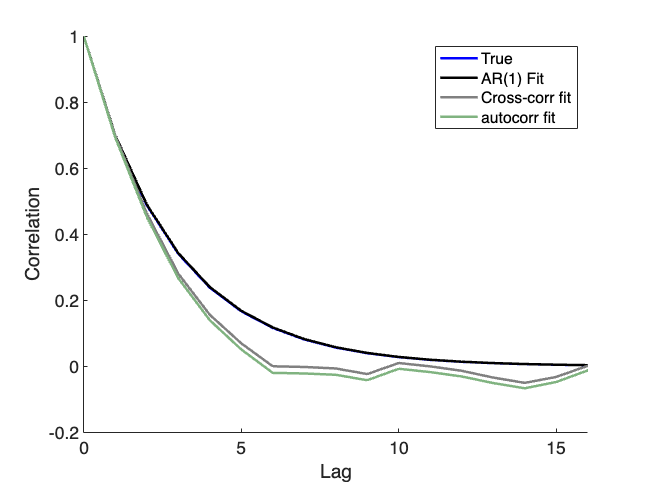

plot([0:16], acf_to_plot(1:17), 'b', 'LineWidth', 2)
plot([0:16], acf_true(1:17), 'k', 'LineWidth', 2)

[C, lags] = xcorr(es3, 16, 'normalized');
C = C(lags >= 0);
lags = lags(lags >= 0);
plot(lags, C, '-', 'Color', [.5 .5 .5], 'LineWidth', 2); 
xlabel('Lag'); ylabel('Correlation');
set(gca, 'XLim', [0 16])

% This produces a very similar result, but is sometimes slightly different:
[acf,lags, bounds] = autocorr(es3);
plot(lags, acf, '-', 'Color', [.5 .7 .5], 'LineWidth', 2); 

legend({'True' 'AR(1) Fit' 'Cross-corr fit' 'autocorr fit'})

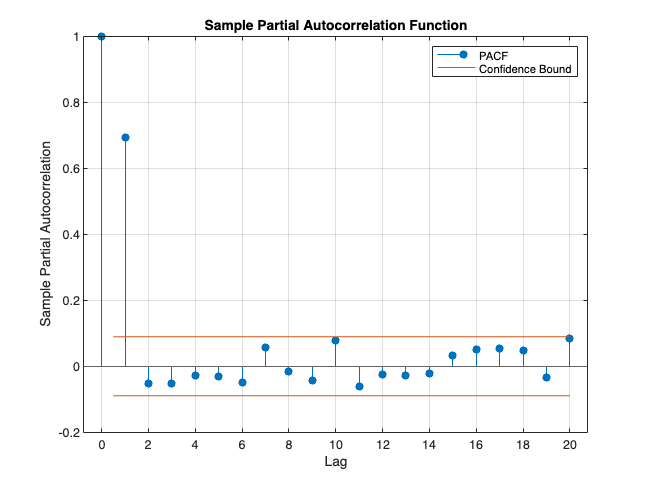


% Plot partial autocorrelation
figure; parcorr(es3)

#### ACF with AR(1) model


n_vals = [500];
n_iter = 50;

rho_2 = [.7];

[~, ~, acf_true] = arp_V(rho_2, n_vals(1));

create_figure('acf')

ans =   Figure (acf) with properties:

      Number: 20
        Name: 'acf'
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


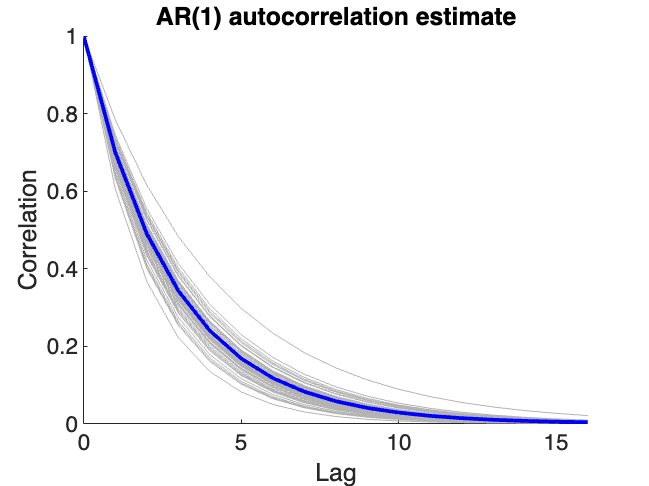


for i = 1:length(n_vals)

    for j = 1:n_iter

        es3 = noise_arp(n_vals(i), rho_2);
        rho_hat = aryule(es3, 1);
        [~, ~, acf_to_plot] = arp_V(-rho_hat(2), n);

        plot([0:16], acf_to_plot(1:17), 'Color', [.7 .7 .7], 'LineWidth', 0.5)

    end

end

plot([0:16], acf_true(1:17), 'b', 'LineWidth', 3)
xlabel('Lag'); ylabel('Correlation');
set(gca, 'XLim', [0 16])
set(gca, 'FontSize', 18)
title('AR(1) autocorrelation estimate')


create_figure('acf2')

ans =   Figure (acf2) with properties:

      Number: 24
        Name: 'acf2'
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


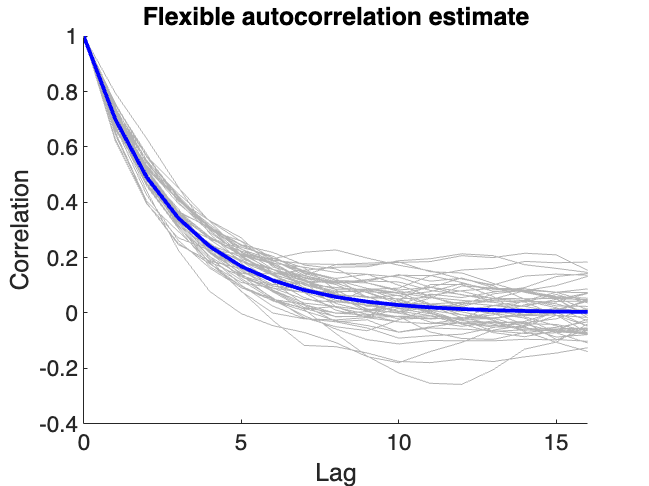


for i = 1:length(n_vals)

    for j = 1:n_iter

        es3 = noise_arp(n_vals(i), rho_2);
        rho_hat = aryule(es3, 1);
        [~, ~, acf_to_plot] = arp_V(-rho_hat(2), n);

        [C, lags] = xcorr(es3, 16, 'normalized');
        C = C(lags >= 0);
        lags = lags(lags >= 0);
        plot(lags, C, '-', 'Color', [.7 .7 .7], 'LineWidth', 0.5);

    end

end

plot([0:16], acf_true(1:17), 'b', 'LineWidth', 3)
xlabel('Lag'); ylabel('Correlation');
set(gca, 'XLim', [0 16])
set(gca, 'FontSize', 18)
title('Flexible autocorrelation estimate')

#### ACF with AR(1) model, different amounts of data


n_vals = [500];
n_iter = 50;

rho_2 = [.7];

[~, ~, acf_true] = arp_V(rho_2, n_vals(1));

create_figure('acf')

ans =   Figure (acf) with properties:

      Number: 20
        Name: 'acf'
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


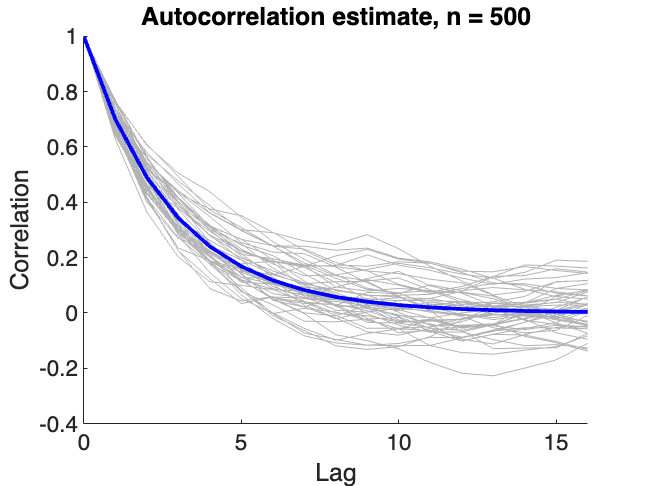


for i = 1:length(n_vals)

    for j = 1:n_iter

        es3 = noise_arp(n_vals(i), rho_2);
        rho_hat = aryule(es3, 1);
        [~, ~, acf_to_plot] = arp_V(-rho_hat(2), n);

        [C, lags] = xcorr(es3, 16, 'normalized');
        C = C(lags >= 0);
        lags = lags(lags >= 0);
        plot(lags, C, '-', 'Color', [.7 .7 .7], 'LineWidth', 0.5);

    end

end

% Add true values
plot([0:16], acf_true(1:17), 'b', 'LineWidth', 3)
xlabel('Lag'); ylabel('Correlation');
set(gca, 'XLim', [0 16])
set(gca, 'FontSize', 18)
title('Autocorrelation estimate, n = 500')


n_vals = [5000];
n_iter = 50;

rho_2 = [.7];

[~, ~, acf_true] = arp_V(rho_2, n_vals(1));

create_figure('acf5000')

ans =   Figure (acf5000) with properties:

      Number: 38
        Name: 'acf5000'
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


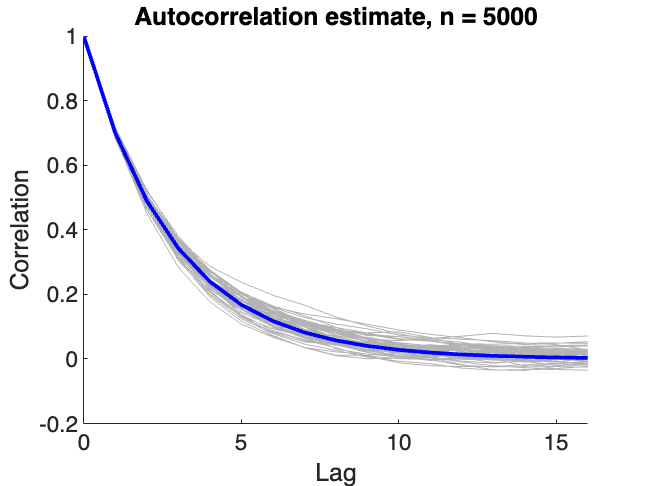


for i = 1:length(n_vals)

    for j = 1:n_iter

        es3 = noise_arp(n_vals(i), rho_2);
        rho_hat = aryule(es3, 1);
        [~, ~, acf_to_plot] = arp_V(-rho_hat(2), n);

        [C, lags] = xcorr(es3, 16, 'normalized');
        C = C(lags >= 0);
        lags = lags(lags >= 0);
        plot(lags, C, '-', 'Color', [.7 .7 .7], 'LineWidth', 0.5);

    end

end

% Add true values
plot([0:16], acf_true(1:17), 'b', 'LineWidth', 3)
xlabel('Lag'); ylabel('Correlation');
set(gca, 'XLim', [0 16])
set(gca, 'FontSize', 18)
title('Autocorrelation estimate, n = 5000')

#### ACF with AR(2) model

% NOTE:  THIS SHOWS THAT AR2 MODEL IS STILL WRONG FOR NOW, AND DOESN'T
% GIVE THE CORRECT VALUES. THIS MATTERS IF WE WANT TO USE THE MATRIX
% VERSION OF AR(>1) WHITENING. BUT WE CAN STILL USE ARYULE WITH FILTER TO DO IT. 

n_vals = [10000];
rho_2 = [.7 .1];

[~, ~, acf_true] = arp_V(rho_2, n_vals);

create_figure('acf')

ans =   Figure (acf) with properties:

      Number: 21
        Name: 'acf'
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


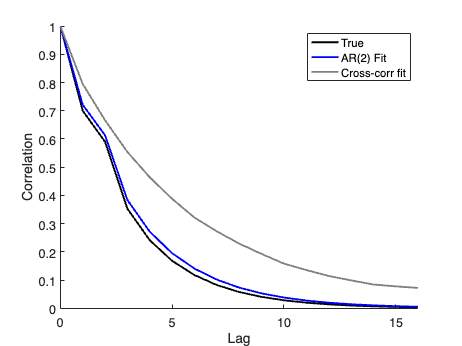

plot([0:16], acf_true(1:17), 'k', 'LineWidth', 2)

for i = 1:length(n_vals)

es3 = noise_arp(n_vals(i), rho_2);
rho_hat = aryule(es3, 2);
[~, ~, acf_to_plot] = arp_V(-rho_hat(2:3), n);

plot([0:16], acf_to_plot(1:17), 'b', 'LineWidth', 2)

[C, lags] = xcorr(es3, 16, 'normalized');
C = C(lags >= 0);
lags = lags(lags >= 0);
plot(lags, C, '-', 'Color', [.5 .5 .5], 'LineWidth', 2); 
xlabel('Lag'); ylabel('Correlation');
set(gca, 'XLim', [0 16])

legend({'True' 'AR(2) Fit' 'Cross-corr fit'})

end

### Calculate whitened time series with ideal (true) coefficients

% see:
% https://online.stat.psu.edu/stat462/node/189/
% - Durbin-Watson test and others
% - Cochrate-Orcutt procedure and others

% Generate innovations (eta) and AR error series (es2)
n = 100;
eta = randn(n, 1);                      % some data, the ideal whitened error timeseries.  where \epsilon(t) ~ N(0,\sigma^2) 
es2 = filter(1, [1, -rho], eta);        % error time series with AR(1)

% Recover innovations with filter.m and plot
es2inv = filter([1 -rho], 1, es2);      % recovered error innovations using ideal model
create_figure('original vs. filtered')

ans =   Figure (original vs. filtered) with properties:

      Number: 33
        Name: 'original vs. filtered'
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


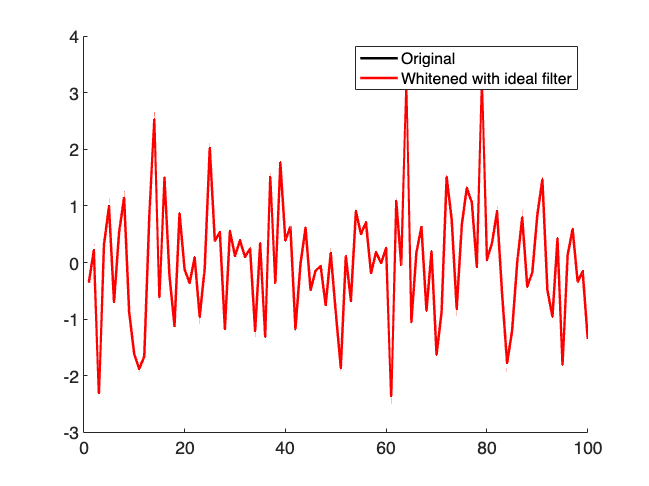

plot(eta, 'k', 'LineWidth', 2); hold on; plot(es2inv, 'r', 'LineWidth', 2)
legend({'Original' 'Whitened with ideal filter'})


corr(eta, es2inv)

ans = 1

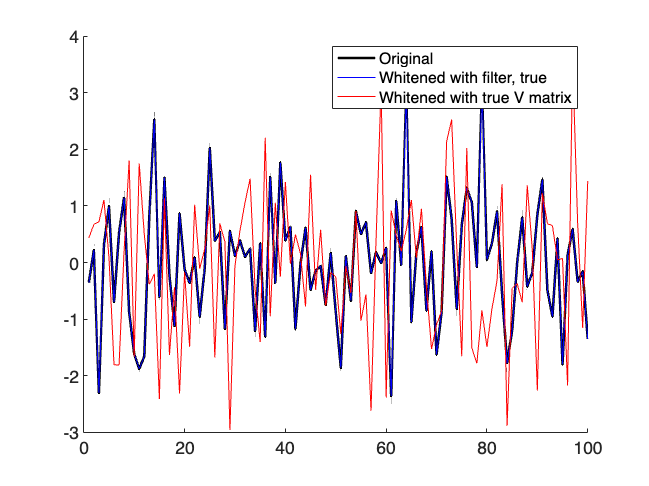


% Recover innovations with inverse of ideal V and plot
[V, K, acf_true] = arp_V(rho, n);
es_w_true = inv(V ^ 0.5) * es;  % Whitened with true V matrix filter
% Note: sqrt(V) is different than V ^ 0.5 here. sqrt() is element-wise, not matrix square root

create_figure('e2');

plot(eta, 'k', 'LineWidth', 2) 

% plot(inv(sqrt(V)) * es, 'r', 'LineWidth', 2) % ideal whitened with true V matrix

plot(es2inv, 'b')
plot(es_w_true, 'r') % ideal whitened with true V matrix
legend({'Original' 'Whitened with filter, true' 'Whitened with true V matrix'})

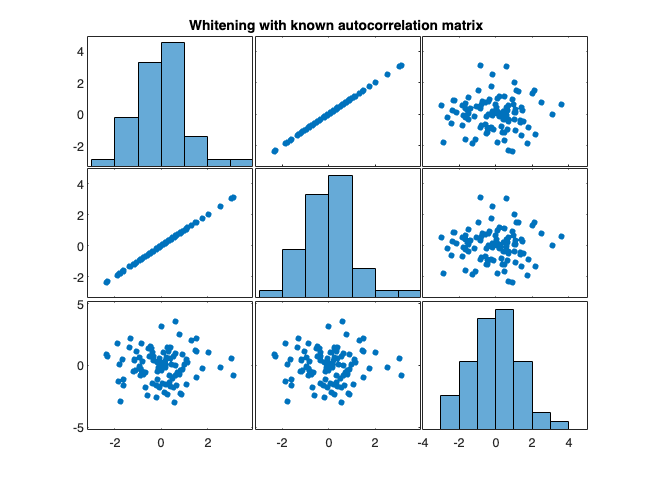


figure; plotmatrix([eta es2inv es_w_true])
title('Whitening with known autocorrelation matrix')

### Estimate filter coefficients from data and whitened time series

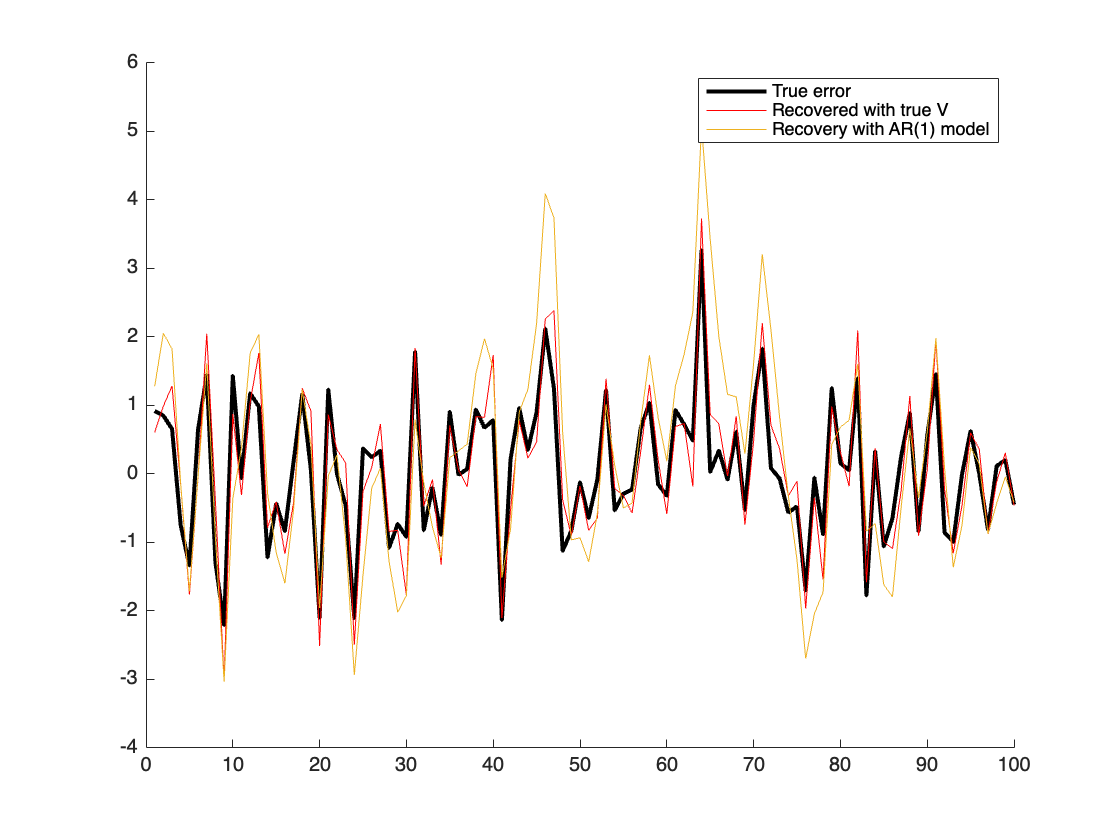

% with noisy V estimate based on data - can we recover the true
% coefficient?
rho_hat = aryule(es, 1);

v_hat_vec = rho_hat(1);

for i = 2:n 

    v_hat_vec(i) = rho_hat(2) .^ (i-1); 

end
V_hat = toeplitz(v_hat_vec);

es_w_aryule = inv(V_hat ^ 0.5) * es;  % Whitened with matrix filter

figure; hold on;
plot(eta, 'k', 'LineWidth', 2) 
plot(es_w_true, 'r') % ideal whitened with true V matrix
plot(es_w_aryule) % recovered: whitened with estimated V matrix

legend({'True error' 'Recovered with true V' 'Recovery with AR(1) model'})


correlation_to_text([eta es2inv es_w_true es_w_aryule], [], {'eta' 'es2inv' 'es_w_true' 'es_w_aryule'});

Crit=0.20	eta	es2inv	es_w_true	es_w_aryule	
eta	1.000	0.973*	0.926*	0.788*	
es2inv	0.973*	1.000	0.878*	0.711*	
es_w_true	0.926*	0.878*	1.000	0.858*	
es_w_aryule	0.788*	0.711*	0.858*	1.000	



% see also:
%[xc,Vi] = canonical_autocorrelation(TR,n,varargin)


### Plot PSD and autocorrelation of timeseries

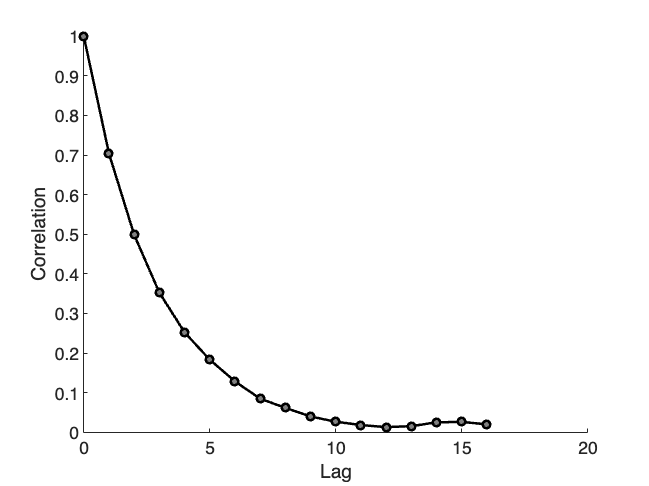

n = 10000;    % number of time points

%  y = noise_arp(n, rho);

eta = randn(n, 1); % some data, the ideal whitened error timeseries.  where \epsilon(t) ~ N(0,\sigma^2) 
% create_figure('e'); 
% plot(eta, 'k', 'LineWidth', 2)

% manual generation: e(t) = \rho e(t-1) + \eta(t)
es = eta(1);
y = zeros(n, 1);
for i = 2:length(eta)
    y(i, 1) = rho * y(i - 1) + eta(i);
end

% Autocorrelation function

[C, lags] = xcorr(y, 16, 'normalized');
C = C(lags >= 0);
lags = lags(lags >= 0);
create_figure('acf'); 
plot(lags, C, 'ko-', 'LineWidth', 2, 'MarkerFaceColor', [.5 .5 .5]); xlabel('Lag'); ylabel('Correlation');

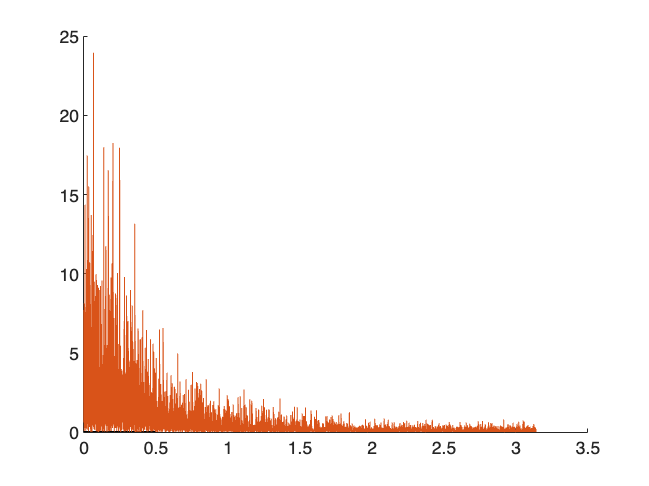




create_figure('fftplot');
[myfft, freq, handle] = fft_plot_scnlab(y, 1);

% different
[Pxx,F] = periodogram(y);
plot(F, Pxx);

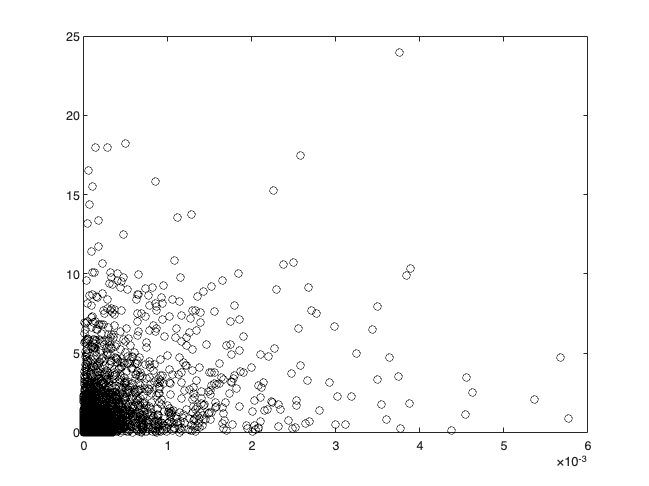


figure; plot(myfft, Pxx(1:5000), 'ko');

corr(myfft, Pxx(1:5000))

ans = 0.3852


A = [1 -rho];

y = filter(1, A, eta);

arcoeffs = aryule(y,2)



[C, lags] = xcorr(y, 16, 'normalized');
C = C(lags >= 0);
lags = lags(lags >= 0);
create_figure('acf'); 
plot(lags, C, 'ko-', 'LineWidth', 2, 'MarkerFaceColor', [.5 .5 .5]); xlabel('Lag'); ylabel('Correlation');


